# Intro to time series

## Definitions

A time series is a quantity changing with time. Its graph has the time axis as horizontal axis. 

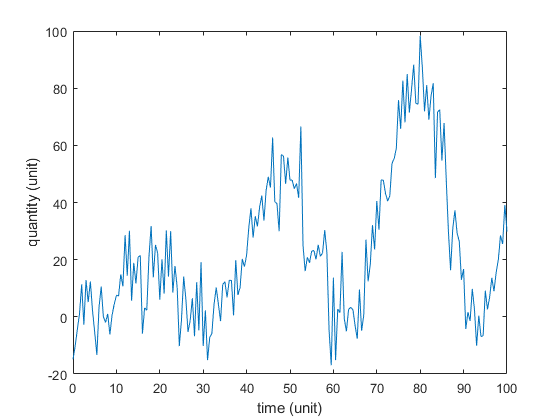

### Examples of time series

- Stock market index

- Temperature - daily, monthly, anual etc.

- Population change

# Simple Linear Regression

This example shows how to perform simple linear regression using the `accidents` dataset.  This data set accidents.mat is available on Matlab.

clear data Fs

disp('Contents of workspace before loading file:')

Contents of workspace before loading file:


whos

  Name               Size             Bytes  Class                                        Attributes

  A                  1x1                  8  double                                                 
  A1                 1x1                  8  double                                                 
  A2                 2x2                 32  double                                                 
  B                  2x1                 16  double                                                 
  B2                 2x1                 16  double                                                 
  M                  1x100              800  double                                                 
  Rsq1               1x1                  8  double                                                 
  Rsq2               1x1                  8  double                                                 
  T                140x1               1120  double                                       

The example also shows you how to calculate the coefficient of determination $R^2$ to evaluate the regressions. The `accidents` dataset contains data for fatal traffic accidents in U.S. states. 

load accidents
% load('accidents.mat')

*Questions: *

*Use the workspace to explore the data set. Or use *`whos.`

*How many variables are in the data set? *

*What are the names of the variables? *

*What are the original sources of the data? *

disp('What are the names of the variables? :')

What are the names of the variables? :


% whos -file accidents.mat
whos('-file','accidents.mat')

  Name              Size            Bytes  Class     Attributes

  datasources       3x1              2700  cell                
  hwycols           1x1                 8  double              
  hwydata          51x17             6936  double              
  hwyheaders        1x17             2622  cell                
  hwyidx           51x1               408  double              
  hwyrows           1x1                 8  double              
  statelabel       51x1              6188  cell                
  ushwydata         1x17              136  double              
  uslabel           1x1               130  cell                




disp('Contents of workspace after loading file:')

Contents of workspace after loading file:


whos

  Name               Size             Bytes  Class                                        Attributes

  A                  1x1                  8  double                                                 
  A1                 1x1                  8  double                                                 
  A2                 2x2                 32  double                                                 
  B                  2x1                 16  double                                                 
  B2                 2x1                 16  double                                                 
  M                  1x100              800  double                                                 
  Rsq1               1x1                  8  double                                                 
  Rsq2               1x1                  8  double                                                 
  T                140x1               1120  double                                       

Linear regression models the relation between a dependent, or response, variable $y$ and one or more independent, or predictor, variables $x_1, ..., x_n$. Simple linear regression considers only one independent variable using the relation


$$y = \beta_0 + \beta_1x + \epsilon,$$


where $\beta_0$ is the y-intercept, $\beta_1$ is the slope (or regression coefficient), and $\epsilon$ is the error term.

Start with a set of $n$ observed values of $x$ and $y$ given by$(x_1,y_1)$, $(x_2,y_2)$, ..., $(x_n,y_n)$. Using the simple linear regression relation, these values form a system of linear equations. Represent these equations in matrix form as


$$\left[\matrix{y_{1}\cr y_{2}\cr \vdots \cr y_{n}\cr}\right] =
\left[\matrix{1 & x_{1}\cr 1 & x_{2}\cr \vdots & \vdots\cr 1 & x_{n}}\right]
\left[ \matrix{\beta_{0} \cr \beta_{1}}\right].$$


Let


$$Y = \left[\matrix{y_{1}\cr y_{2}\cr \vdots \cr y_{n}\cr}\right], 
X = \left[\matrix{1 & x_{1}\cr 1 & x_{2}\cr \vdots & \vdots\cr 1 &
x_{n}}\right], B = \left[ \matrix{\beta_{0} \cr \beta_{1}}\right].$$


The relation is now $Y = XB$.

In MATLAB, you can find $B$ using the [mldivide](docid:matlab_ref.btg5qam) operator as B = X\Y. 

From the dataset `accidents`, load state accident data in `y` and state population data in `x`. Find the linear regression relation $y = \beta_1x$ between the accidents in a state and the population of a state using the `\` operator. The `\` operator performs a least-squares regression. 

%load accidents
x = hwydata(:,14); %Population of states
y = hwydata(:,4);  %Accidents per state
b1 = x\y

b1 = 1.3727e-04

`b1` is the slope or regression coefficient. The linear relation is $y = \beta_1x = 0.0001372x$.

Calculate the accidents per state `yCalc` from `x` using the relation. Visualize the regression by plotting the actual values `y` and the calculated values `yCalc`.

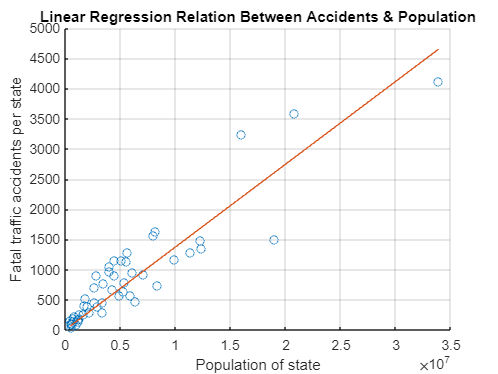

yCalc1 = b1*x;
scatter(x,y)
hold on
plot(x,yCalc1)
xlabel('Population of state')
ylabel('Fatal traffic accidents per state')
title('Linear Regression Relation Between Accidents & Population')
grid on

Improve the fit by including a y-intercept $\beta_0$ in your model as $y = \beta_0 + \beta_1x$. Calculate $\beta_0$ by padding `x` with a column of ones and using the `\` operator. 

X = [ones(length(x),1) x];
b = X\y

b =   142.7120
    0.0001


This result represents the relation $y = \beta_0 + \beta_1x = 142.7120 + 0.0001256x$.

Use `format short e` to change the format of the output for `b.`

Visualize the relation by plotting it on the same figure.

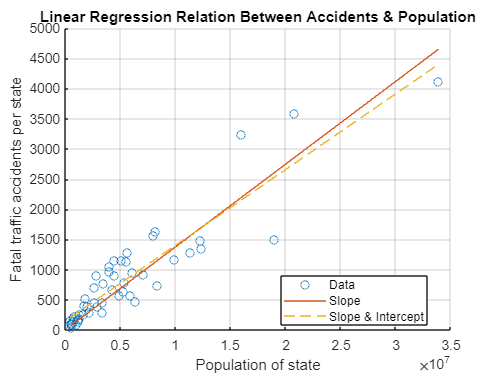

yCalc2 = X*b;
plot(x,yCalc2,'--')
legend('Data','Slope','Slope & Intercept','Location','best');

From the figure, the two fits look similar. One method to find which is the better fit is to calculate the coefficient of determination, $R^2$. $R^2$ is one measure of how well a model can predict the data, and falls between $0$ and $1$. The higher the value of $R^2$, the better the model is at predicting the data.

Where $\hat{y}$ represents the calculated values of $y$ and $\bar{y}$ is the mean of $y$, $R^2$ is defined as


$$ R^2 = 1 - \frac{\sum\limits_{i=1}^n \left(y_i - \hat{y}_i\right)^2}{\sum\limits_{i=1}^n \left(y_i - \bar{y}\right)^2}.$$


Find the better fit of the two fits by comparing values of $R^2$. As the $R^2$ values show, the second fit that includes a y-intercept is better.

Rsq1 = 1 - sum((y - yCalc1).^2)/sum((y - mean(y)).^2)

Rsq1 = 0.8222

Rsq2 = 1 - sum((y - yCalc2).^2)/sum((y - mean(y)).^2)

Rsq2 = 0.8382

### Examples of Linear Regression script

% linregr: linear regression curve fitting
% Least squares fit of straight line from the data array x and y
% by solving the normal equations
% input:
% x = independent variable
% y = dependent variable
% output:
% b = vector of slope, b(2), and intercept, b(1)
% r2 = coefficient of determination
n = length(x);
if length(y)~=n, error('x and y must be same length'); end
x = x(:); y = y(:); % convert to column vectors
sx = sum(x); sy = sum(y);
sx2 = sum(x.*x); sxy = sum(x.*y); 
% Use the normal equations in matrix form as on lecture slide 35
A=[size(x,1) sx; sx sx2]; %Coefficient matrix
B=[sy; sxy];
b=A\B;
%Coefficient of determination
yhat=b(2)*x+b(1);
r2 = 1 - sum((y - yhat).^2)/sum((y - mean(y)).^2)

r2 = 0.8382

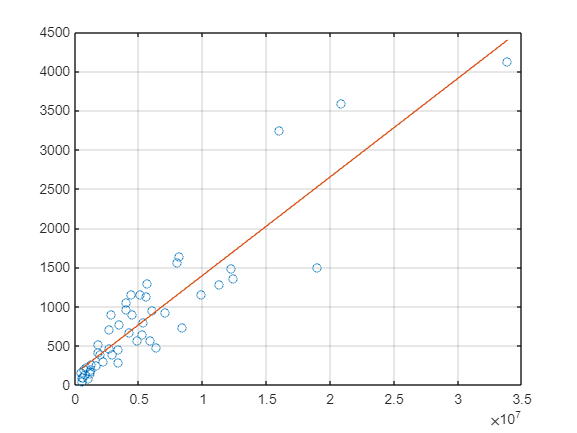

% create plot of data and best fit line
xp = linspace(min(x),max(x),2);
yp = b(2)*xp+b(1);
clf
plot(x,y,'o',xp,yp)
grid on

*Copyright 2015 The MathWorks, Inc. Editted by H. Chung 2019.*

At the links below there are lists of sample data sets included in Matlab: 

[https://au.mathworks.com/help/matlab/import_export/matlab-example-data-sets.html](https://au.mathworks.com/help/matlab/import_export/matlab-example-data-sets.html)

[https://au.mathworks.com/help/stats/sample-data-sets.html](https://au.mathworks.com/help/stats/sample-data-sets.html)

#### Challenge problem

On lecture slide 45 the following sample code is given for the least square line. 

Check that the least squares line is the same as for the code in the previous section. 

Show how the formulae for the slope, the intercept and the coeffiecient of determination that are used in this code, are obtained. 

% linregr: linear regression curve fitting
% Least squares fit of straight from the dasta array x and y
% line to data by solving the normal equations
% input:
% x = independent variable
% y = dependent variable
% output:
% a = vector of slope, a(1), and intercept, a(2)
% r2 = coefficient of determination
n = length(x);
if length(y)~=n, error('x and y must be same length'); end
x = x(:); y = y(:); % convert to column vectors
sx = sum(x); sy = sum(y);
sx2 = sum(x.*x); sxy = sum(x.*y); sy2 = sum(y.*y);
a(1) = (n*sxy-sx*sy)/(n*sx2-sx^2);
a(2) = sy/n-a(1)*sx/n;
r2 = ((n*sxy-sx*sy)/sqrt(n*sx2-sx^2)/sqrt(n*sy2-sy^2))^2

r2 = 0.8382

% create plot of data and best fit line
xp = linspace(min(x),max(x),2);
yp = a(1)*xp+a(2);
plot(x,y,'o',xp,yp)
grid on

#### Note on scatter plot

**Example**: Create `x` as 200 equally spaced values between 0 and $3\pi$. Create `y` as cosine values with random noise. Then, create a scatter plot.

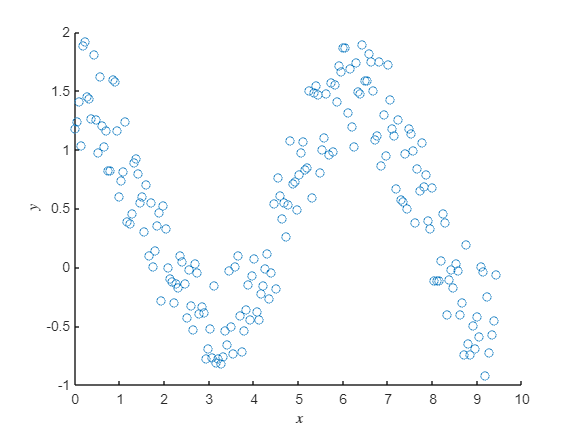

x = linspace(0,3*pi,200);
y = cos(x) + rand(1,200);  % rand must have the same size as x
scatter(x,y)
xlabel('$x$','Interpreter','Latex')
ylabel('$y$','Interpreter','Latex') 

## Time Series Regression of Airline Passenger Data

This example shows how to analyze time series data using Statistics. 

**Some of the commands used here need to be explored on your own.*

## Air Passenger Data

First we create an array of monthly counts of airline passengers, measured in thousands, for the period January 1949 through December 1960.

%   1949 1950 1951 1952 1953 1954 1955 1956 1957 1958 1959 1960
y = [112  115  145  171  196  204  242  284  315  340  360  417    % Jan
     118  126  150  180  196  188  233  277  301  318  342  391    % Feb
     132  141  178  193  236  235  267  317  356  362  406  419    % Mar
     129  135  163  181  235  227  269  313  348  348  396  461    % Apr
     121  125  172  183  229  234  270  318  355  363  420  472    % May
     135  149  178  218  243  264  315  374  422  435  472  535    % Jun
     148  170  199  230  264  302  364  413  465  491  548  622    % Jul
     148  170  199  242  272  293  347  405  467  505  559  606    % Aug
     136  158  184  209  237  259  312  355  404  404  463  508    % Sep
     119  133  162  191  211  229  274  306  347  359  407  461    % Oct
     104  114  146  172  180  203  237  271  305  310  362  390    % Nov
     118  140  166  194  201  229  278  306  336  337  405  432 ]; % Dec
% Source:
% Hyndman, R.J., Time Series Data Library,
% http://www-personal.buseco.monash.edu.au/~hyndman/TSDL/.
% Copied in October, 2005.

## Create Time Series Object

When we create a time series object, we can keep the time information along with the data values. We have monthly data, so we create an array of dates and use it along with the Y data to create the time series object.

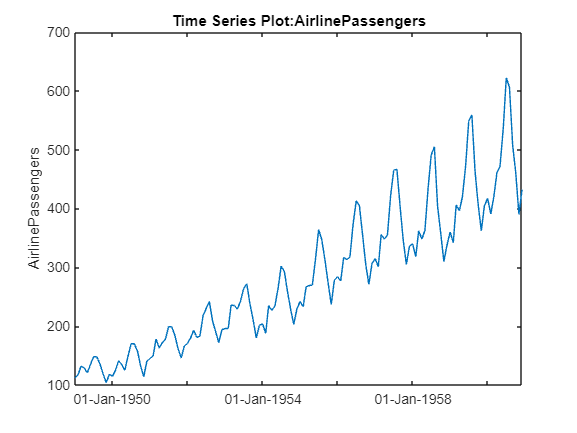

yr = repmat((1949:1960),12,1);
mo = repmat((1:12)',1,12);
time = datestr(datenum(yr(:),mo(:),1));
ts = timeseries(y(:),time,'name','AirlinePassengers');
ts.TimeInfo.Format = 'dd-mmm-yyyy';
tscol = tscollection(ts);
plot(ts)

## Examine Trend and Seasonality

This series seems to have a strong seasonal component, with a trend that may be linear or quadratic. Furthermore, the magnitude of the seasonal variation increases as the general level increases. Perhaps a log transformation would make the seasonal variation be more constant. First we'll change the axis scale.

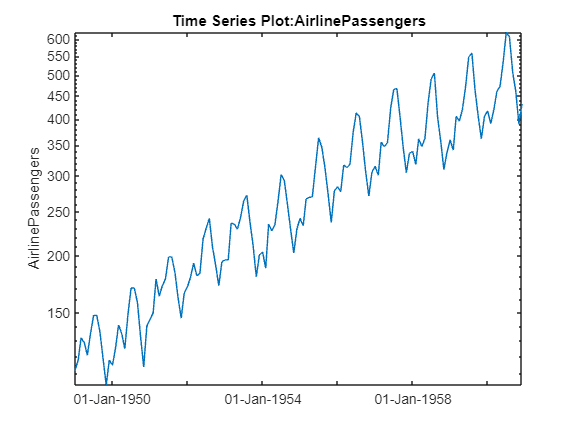

h_gca = gca;
h_gca.YScale = 'log';

It appears that it would be easier to model the seasonal component on the log scale. We'll create a new time series with a log transformation.

tscol = addts(tscol, log(ts.data), 'logAirlinePassengers');
logts = tscol.logAirlinePassengers;

Now let's plot the yearly averages, with monthly deviations superimposed. We want to see if the month-to-month variation within years appears constant. For these manipulations treating the data as a matrix in a month-by-year format, it's more convenient to operate on the original data matrix.

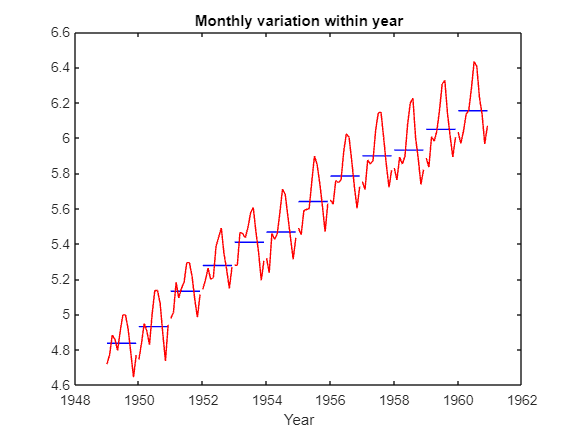

t = reshape(datenum(time),12,12);
logy = log(y);
ymean = repmat(mean(logy),12,1);
ydiff = logy - ymean;
x = yr + (mo-1)/12;
plot(x,ymean,'b-',x,ymean+ydiff,'r-')
title('Monthly variation within year')
xlabel('Year')

Now let's reverse the years and months, and try to see if the year-to-year trend is constant for each month.

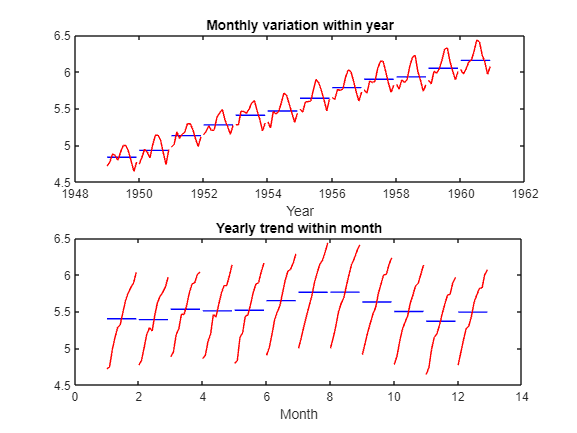

h_gca = gca;
h_gca.Position = [0.13   0.58   0.78   0.34];
subplot(2,1,2);
t = reshape(datenum(time),12,12);
mmean = repmat(mean(logy,2),1,12);
mdiff = logy - mmean;
x = mo + (yr-min(yr(:)))/12;
plot(x',mmean','b-',x',(mmean+mdiff)','r-')
title('Yearly trend within month')
xlabel('Month')

## Model Trend and Seasonality

Let's attempt to model this series as a linear trend plus a seasonal component.

subplot(1,1,1);
X = [dummyvar(mo(:)), logts.time];
[b,~,resid] = regress(logts.data, X);
tscol = addts(tscol,X*b,'Fit1')

Time Series Collection Object: unnamed

Time vector characteristics

      Start date            01-Jan-1949
      End date              01-Dec-1960

Member Time Series Objects:

      AirlinePassengers
      logAirlinePassengers
      Fit1




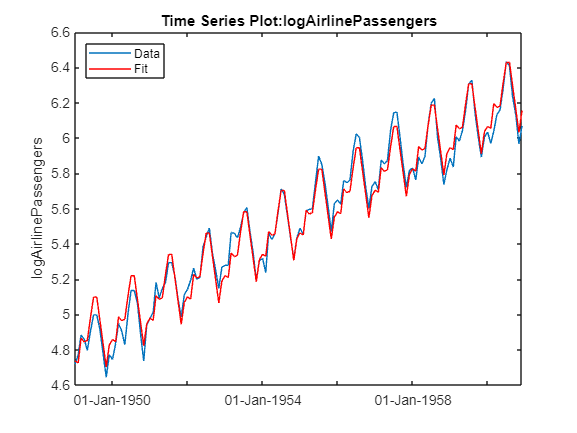

plot(logts)
hold on
plot(tscol.Fit1,'Color','r')
hold off
legend('Data','Fit','location','NW')

Based on this graph, the fit appears to be good. The differences between the actual data and the fitted values may well be small enough for our purposes.

But let's try to investigate this some more. We would like the residuals to look independent. If there is autocorrelation (correlation between adjacent residuals), then there may be an opportunity to model that and make our fit better. Let's create a time series from the residuals and plot it.

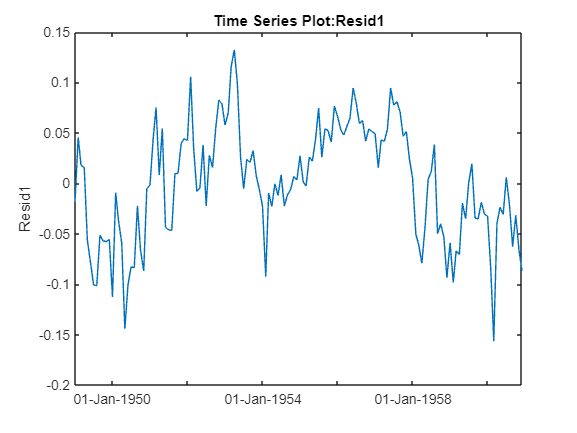

tscol = addts(tscol,resid,'Resid1');
plot(tscol.Resid1)

The residuals do not look independent. In fact, the correlation between adjacent residuals looks quite strong. We can test this formally using a Durbin-Watson test.

[p,dw] = dwtest(tscol.Resid1.data, X)

p = 7.7787e-30

dw = 0.4256

A low p-value for the Durbin-Watson statistic is an indication that the residuals are correlated across time. A typical cutoff for hypothesis tests is to decide that p<0.05 is significant. Here the very small p-value gives strong evidence that the residuals are correlated.

We can attempt to change the model to remove the autocorrelation. The general shape of the curve is high in the middle and low at the ends. This suggests that we should allow for a quadratic trend term. However, it also appears that autocorrelation will remain after we add this term. Let's try it.

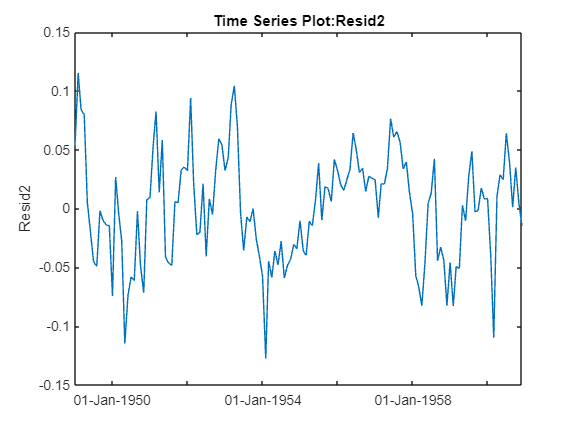

X = [dummyvar(mo(:)), logts.time, logts.time.^2];
[b2,bint,resid2] = regress(logts.data, X);
tscol = addts(tscol,resid2,'Resid2');
plot(tscol.Resid2);

[p,dw] = dwtest(tscol.Resid2.data, X)

p = 8.7866e-20

dw = 0.6487

Adding the squared term did remove the pronounced curvature in the original residual plot, but both the plot and the new Durbin-Watson test show that there is still significant correlation in the residuals.

Autocorrelation like this could be the result of other causes that are not captured in our X variable. Perhaps we could collect other data that would help us improve our model and reduce the correlation. In the absence of other data, we might simply add another parameter to the model to represent the autocorrelation. Let's do that, removing the squared term, and using an autoregressive model for the error.

In an autoregressive process, we have two stages:

Unlike in the usual regression model when we would like the residual series `r(t)` to be a set of independent values, this model allows the residuals to follow an autoregressive model with its own error term `u(t)` that consists of independent values.

To create this model, we want to write an anonymous function `f` to compute fitted values `Yfit`, so that `Y-Yfit` gives the u values:

In this anonymous function we combine `[rho; b]` into a single parameter vector `c`. The resulting residuals look much closer to an uncorrelated series.

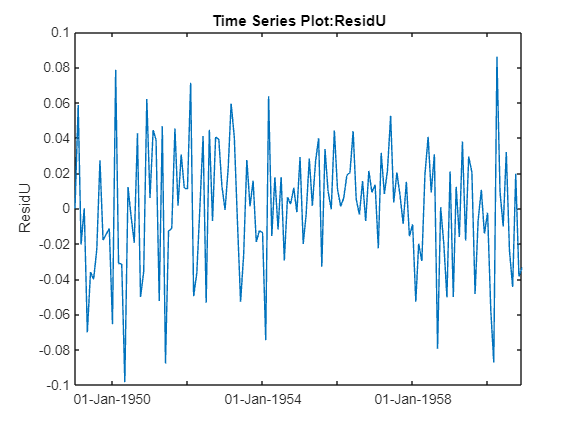

r = corr(resid(1:end-1),resid(2:end));  % initial guess for rho
X = [dummyvar(mo(:)), logts.time];
Y = logts.data;
f = @(c,x) [Y(1); c(1)*Y(1:end-1) + (x(2:end,:)- c(1)*x(1:end-1,:))*c(2:end)];
c = nlinfit(X,Y,f,[r;b]);

u = Y - f(c,X);
tscol = addts(tscol,u,'ResidU');
plot(tscol.ResidU);

*Copyright 2005- The MathWorks, Inc. Edited by H. Chung 2019.*